## Daten Laden und Data Store erstellen

filename = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFürTraining\99_Trainingsdatensätze\Sortierung1";
imdsSchilder = imageDatastore(filename, "IncludeSubfolders", true, "LabelSource", "foldernames");

## Explorative Datenanalyse

% numImgs = length(imdsZahlen.Files)
countEachLabel(imdsSchilder)

ans = 2×2 table
          Label           Count
    __________________    _____

    BilderOhneSchilder     543 
    Schilder               106 


%genau gleiche viele einträge von jedem Label
numPerLabel =min(countEachLabel(imdsSchilder).Count)

numPerLabel = 106

% Labels extrahieren
allLabels = unique(imdsSchilder.Labels);
balancedFiles = [];

for i = 1:numel(allLabels)
    label = allLabels(i);
    % Alle Bilder mit diesem Label holen
    idx = find(imdsSchilder.Labels == label);
    % Wenn mehr als numPerLabel vorhanden, zufällig auswählen
    if numel(idx) >= numPerLabel
        selectedIdx = randsample(idx, numPerLabel);
        balancedFiles = [balancedFiles; imdsSchilder.Files(selectedIdx)];
    else
        warning("Label '%s' hat weniger als %d Bilder.", label, numPerLabel);
    end
end

% Neuen ImageDatastore mit ausgewählten Dateien erstellen
balancedDS = imageDatastore(balancedFiles, 'Labels', categorical(cellstr(extractBetween(balancedFiles, ...
    fullfile(filename, '\'), filesep))));

% img = read(imdsZahlen);
% figure;
% imshow(img)
% img = readimage(imdsZahlen, 1650);
% figure;
% imshow(img)
% size(img)


## Erzeuge Trainings- und Validierungsdatensatz

[imdsTrain, imdsValidation] = splitEachLabel(balancedDS, 0.8, "randomized");

## **Bilder de zusortieren sind Laden**

%zusortierende Bilder laden, label wie Label des bisherigen Schildsbezeichnen
files = dir("C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten\AusgeschnittenFürTraining\5_Polygon_Schilder\Stoppschild\*.png");
fileList = fullfile({files.folder}, {files.name});
labels = repelem("Schilder", numel(fileList));
imdsSchilder2 = imageDatastore(fileList, "Labels", categorical(labels));

## Defeniere Netzwerkschichten

% Einfaches CNN definieren

layers = [
    imageInputLayer([48, 48, 3], "Name", "input", "Normalization", "none")
    convolution2dLayer(3, 8, 'Padding', 'same', "Name", "conv_1")
    reluLayer("Name", "relu_1")
    maxPooling2dLayer(2, 'Stride', 2,"Name", "maxpool_1")
    convolution2dLayer(3, 16, 'Padding', 'same',"Name", "conv_2")
    reluLayer("Name", "relu_2")
    maxPooling2dLayer(2, 'Stride', 2,  "Name", "maxpool_2")
    fullyConnectedLayer(2, "Name", "fc") 
    softmaxLayer("Name", "softmax")
    classificationLayer("Name", "output")
];


## Exploration des Netzwerkes

% layers(1).Name
% layers(1). InputSize
% layers(end-2).OutputSize

## Anpassen Hyperparameter

%sicherstellen das alle Bilder die gleiche größe haebn
augTrain  = augmentedImageDatastore([48 48 3], imdsTrain, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
augVal = augmentedImageDatastore([48 48 3], imdsValidation, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
aug2= augmentedImageDatastore([48 48 3], imdsSchilder2, ...
    'ColorPreprocessing', 'none', ...
    'OutputSizeMode', 'resize');
% Trainingsparameter Schlake
% opts = trainingOptions("adam", "ValidationData", augVal, "Shuffle", "every-epoch", "Plots", "training-progress","InitialLearnRate",0.01);
% Trainingsparameter 
options = trainingOptions('adam', ...
 'MaxEpochs', 25, ...
 "InitialLearnRate", 0.0005, ...
    'MiniBatchSize', 16, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots', 'training-progress');

## Training

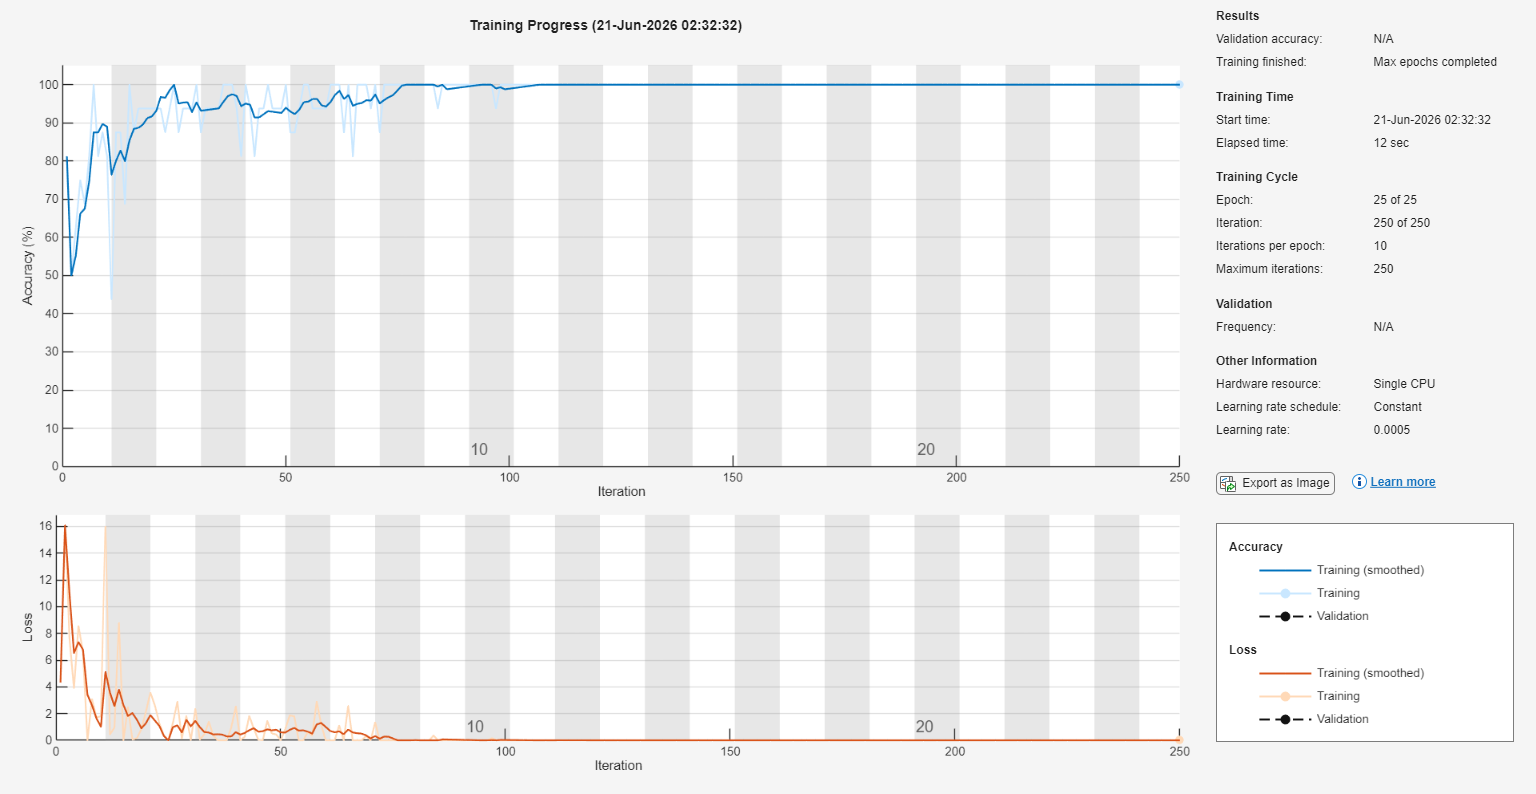

net = trainNetwork(augTrain, layers, options);

## Schätzung

% Testen des Neuronalen Netzes
trainPreds = classify(net,augTrain);
testPreds = classify(net,augVal);
testpreds2 = classify(net,aug2);

## **Falsche Ergebnisse ausgeben**

%Falsch erkantte Bilder anzeigen
trueLabelsTrain = imdsTrain.Labels;
trueLabelsVali = imdsValidation.Labels;
trueLabelsVali2 = imdsSchilder2.Labels;

wrongIdxtrain = find(trainPreds ~= trueLabelsTrain);
wrongIdxVali = find(testPreds ~= trueLabelsVali);

%Alle Bilder, der zusortierenden Bilder in ein Datenset, bei denen gesagt
%wurde das sie Schilder sind
wrongIdxVali2 = find(testpreds2 == trueLabelsVali2);


% for i = 1:length(wrongIdxtrain)
%     img = readimage(imdsTrain, wrongIdxtrain(i));
%     figure;
%     imshow(img);
%     title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
%         string(trainPreds(wrongIdxtrain(i))), string(trueLabelsTrain(wrongIdxtrain(i)))));
% end

% for i = 1:length(wrongIdxVali)
%     img = readimage(imdsValidation, wrongIdxVali(i));
%     figure;
%     imshow(img);
%     title(sprintf("Falsch erkannt: Vorhersage = %s, Richtig = %s", ...
%         string(testPreds(wrongIdxVali(i))), string(trueLabelsVali(wrongIdxVali(i)))));
% end



## Evaluierung

% Evaluierung des Modelles
confMat = confusionmat(imdsTrain.Labels, trainPreds);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 100.00%


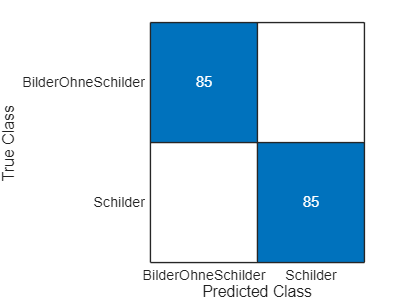

confusionchart(imdsTrain.Labels, trainPreds);

confMat = confusionmat(imdsValidation.Labels, testPreds);
accuracy = sum(diag(confMat)) / sum(confMat(:));
fprintf('Accuracy: %.2f%%\n', accuracy * 100);

Accuracy: 100.00%


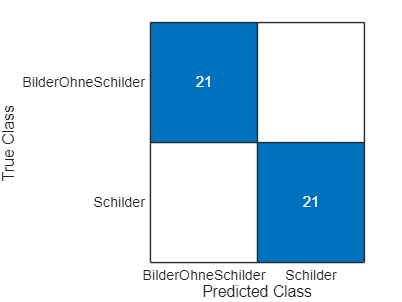

confusionchart(imdsValidation.Labels, testPreds);

% lg = layerGraph(net.Layers);
% dlnet = dlnetwork(lg);


targetFolder = fullfile("C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\09_Trainingsdaten", "ErkannteSchilder");
if ~exist(targetFolder, 'dir')
    mkdir(targetFolder);
end

%Bilder in Ordner kopieren bei den vorhergast wurde sie sind Schilder
for i = 1:length(wrongIdxVali2)
     srcFile = imdsSchilder2.Files{wrongIdxVali2(i)};
    [~, name, ext] = fileparts(srcFile);
    movefile(srcFile, fullfile(targetFolder, [name, ext]));
end